clear; clc; close all

## Manual PID Tuning

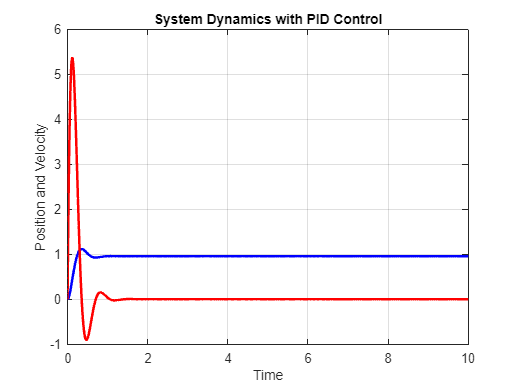

clear compute_pid_control

% Defining System Parameters
dynamics_params.mass = 1.0;                 % Mass of the object
dynamics_params.spring_constant = 5.0;      % Spring constant of the spring
dynamics_params.damping_coefficient = 0.1;  % Damping coefficient of the damper

% Initialize PID gains
gains = [100; 0.001; 10];

% Initial state [position; velocity]
initial_state = [0; 0];

% Desired state [desired_position; desired_velocity]
desired_state = [1; 0];

% Time span for simulation
tspan = [0, 10];  % Start time and end time


clear compute_pid_control
% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains, y, desired_state), dynamics_params), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control');
grid on;


cost_manual = cost(gains,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_manual = 671.6292

## PID Gain Optimisation - ODE45

clear compute_pid_control

% interior point
options = optimoptions("fmincon","Display","iter",...
    "Algorithm","interior-point",...
    "EnableFeasibilityMode",true,...
    "SubproblemAlgorithm","cg");
gains_interiorP = fmincon(@(gains)cost(gains,desired_state,initial_state,dynamics_params,tspan,ones(2)),[100;0.01;10],[],[],[],[],[],[],@(gains)DynamicConstODE(gains,desired_state,initial_state,dynamics_params,tspan),options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    1.747096e+03    2.302e-02    4.529e+11
    1      12    1.579558e+03    7.857e-03    3.964e+06    1.083e-01

Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<

gains_interiorP =    99.9011
    0.0166
    9.9564


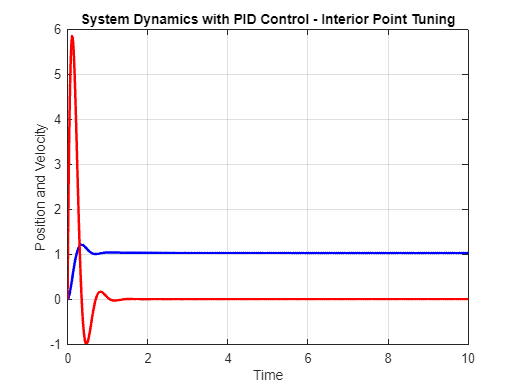



clear compute_pid_control
% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains_interiorP, y, desired_state), dynamics_params), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Interior Point Tuning');
grid on;


cost_interiorP = cost(gains_interiorP,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_interiorP = 2.1104e+03

## PID Gain Optimisation - Genetic Algorithm

clear compute_pid_control

% Define the GA options
ga_options = optimoptions('ga', 'Display', 'iter', 'PopulationSize', 20, 'MaxGenerations', 25);

% Set the lower and upper bounds for the PID gains
lb = [10, 0.0005, 1]; % Lower bounds for Kp, Ki, and Kd
ub = [200, 0.06, 20]; % Upper bounds for Kp, Ki, and Kd

% Perform the optimization using GA
gains_ga = ga(@(gains) cost(gains, desired_state, initial_state, dynamics_params, tspan, ones(2)), 3, [], [], [], [], lb, ub, @(gains) DynamicConstODE(gains, desired_state, initial_state, dynamics_params, tspan), ga_options)


Single objective optimization:
3 Variable(s)
4 Nonlinear equality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1            540       160.078       0.2932      0
    2           1060       246.709       0.2968      0
    3           1580       685.281      0.08333      0
    4           2100       946.643     0.005962      0
    5           2620       1042.95     0.001904      0
    6           3140       1022.46     0.002729      0
    7           3660       1030.85     0.001831      0
    8           4180        1022.3     0.001908      0
    9           4700        934.59     0.002258      0
   10           5220       938.031     0.002283      0
   11           5740       990.731     0.001564      0
   12           6260    

gains_ga =    10.3906    0.0591    3.7969


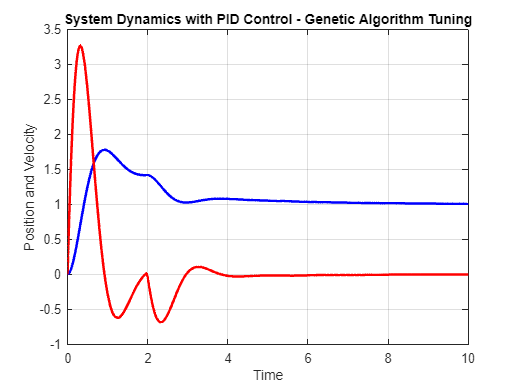



clear compute_pid_control
% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains_ga, y, desired_state), dynamics_params), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Genetic Algorithm Tuning');
grid on;


cost_ga = cost(gains_ga,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_ga = 963.8272

## PID Gain Optimisation - Particle Swarm

clear compute_pid_control

% Define the GA options
ps_options = optimoptions('particleswarm', 'Display', 'iter', 'SwarmSize', 100);

% Set the lower and upper bounds for the PID gains
lb = [10, 0.0005, 1]; % Lower bounds for Kp, Ki, and Kd
ub = [200, 0.06, 20]; % Upper bounds for Kp, Ki, and Kd

% Perform the optimization using GA
gains_ps = particleswarm(@(gains) cost(gains, desired_state, initial_state, dynamics_params, tspan, ones(2)), 3, lb, ub, ps_options)


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0             100           402.8            1853        0
    1             200           159.7            2023        0
    2             300           159.7            1547        1
    3             400           159.7           923.2        2
    4             500           159.7             680        3
    5             600           159.7           837.4        4
    6             700           159.7            1184        5
    7             800           159.7           475.4        6
    8             900           159.7           623.6        7
    9            1000           159.7           590.1        8
   10            1100           153.7           668.1        0
   11            1200           153.7           665.6        1
   12            1300           151.5           417.1        0
   13            1400           151.5           

gains_ps =    10.0000    0.0005    6.5851


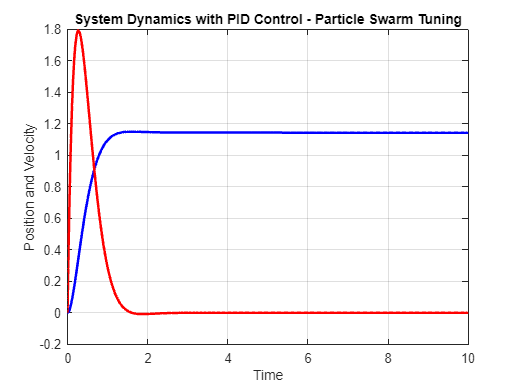



clear compute_pid_control
% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains_ps, y, desired_state), dynamics_params), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Particle Swarm Tuning');
grid on;


cost_ps = cost(gains_ps,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_ps = 445.5313

## PID Gain Optimisation - with Pseudospectral Formulation

N = 21;

init = zeros(5, N+1);
init(3,1) = gains_ps(1);
init(4,1) = gains_ps(2);
init(5,1) = gains_ps(3);

options = optimoptions('fmincon','Display','iter','MaxFunctionEvaluations',1e11,'Algorithm','sqp',"EnableFeasibilityMode",true,'MaxIterations',5e3);

tf = 10; 
desired_state = [1; 0];
initial_state = [0; 0];
Q = ones(2);

[Z,~,flg] = fmincon(@(Z)cost_pseudospectral(Z,desired_state,Q,N,tf),init,[],[],[],[],[],[],@(Z)NonLinCon_PseudoSpectral(Z,initial_state,desired_state,dynamics_params,N,tf),options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         111    9.988662e+00     1.000e+01     1.000e+00     0.000e+00     1.492e+00  
    1         222    4.050588e-01     4.933e+00     1.000e+00     6.768e+00     2.175e+03  
    2         333    7.010299e-01     3.089e-01     1.000e+00     1.683e+00     3.871e+02  
    3         444    7.681941e-01     2.391e-01     1.000e+00     1.912e+00     3.966e+02  
    4         561    7.730113e-01     2.333e-01     1.176e-01     5.126e-01     3.992e+02  
    5         680    7.776852e-01     2.297e-01     5.765e-02     3.401e-01     4.009e+02  
    6         799    7.829722e-01     2.263e-01     5.765e-02     3.185e-01     4.025e+02  
    7         917    7.914478e-01     2.219e-01     8.235e-02     4.339e-01     4.047e+02  
    8        1035    8.005608e-01     2.180e-01     8.235e-02     4.047e-01     4.

gains_psuedospectral = Z(3:5,1).'

gains_psuedospectral =    29.4472    0.0600    8.1577


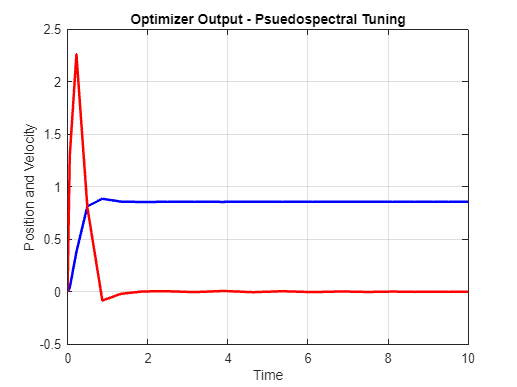


[nodes,wk] = clencurt(N);
tspan_ = ((flip(nodes)+1)/2).*tf;

% Extract position and velocity for plotting
position = Z(1, :);
velocity = Z(2, :);

% Plot the results
figure;
plot(tspan_, position, 'b', 'LineWidth', 2);
hold on;
plot(tspan_, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('Optimizer Output - Psuedospectral Tuning');
grid on;

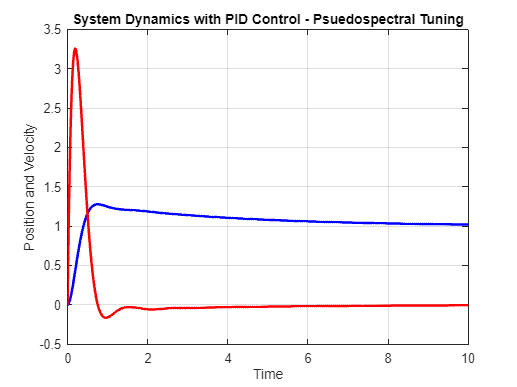

clear compute_pid_control

% Use numerical integration (ode45) to simulate the system dynamics with PID control
[t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains_psuedospectral, y, desired_state), dynamics_params), tspan, initial_state);

% Extract position and velocity for plotting
position = y(:, 1);
velocity = y(:, 2);

% Plot the results
figure;
plot(t, position, 'b', 'LineWidth', 2);
hold on;
plot(t, velocity, 'r', 'LineWidth', 2);
xlabel('Time');
ylabel('Position and Velocity');
title('System Dynamics with PID Control - Psuedospectral Tuning');
grid on;


cost_pseudospec = cost(gains_psuedospectral,desired_state,initial_state,dynamics_params,tspan,ones(2))

cost_pseudospec = 1.2003e+03

## Non-Linear Constraint for Pseudospectral Optimisation

function [c,ceq] = NonLinCon_PseudoSpectral(Z,initial_state,desired_state,dynamics_params,N,tf)
    
    state = Z(1:2,:);
    gains = Z(3:5,1);

    Kp = gains(1);
    Ki = gains(2);
    Kd = gains(3);

    c(1) = Kp - 200;
    c(2) = Ki - 0.06;
    c(3) = Kd - 20;
    c(4) = 10 - Kp;
    c(5) = 0.0005 - Ki;
    c(6) = 1 - Kd;

    % Use Guass-Quadrature integration to simulate system dynamics with PID
    error = desired_state(1,:) - state(1,:);
    integral = zeros(size(error));
    integral(:,1) = error(:,1);

    velocity_error = desired_state(2,:) - state(2,:);

    [~,wk] = clencurt(N);

    for i = 2:size(state,2)
        integral(:,i) = integral(:,i-1) + wk(i)*error(:,i);
    end

    D = -DCPeyret(N+1);

    % Unpack state variables
    position = state(1,:);
    velocity = state(2,:);

    % Unpack dynamics parameters from the struct
    mass = dynamics_params.mass;
    spring_constant = dynamics_params.spring_constant;
    damping_coefficient = dynamics_params.damping_coefficient;

    input = Kp*error + Ki*integral + Kd*velocity_error;

    % Compute the acceleration (second derivative of position)
    acceleration = (input - damping_coefficient * velocity - spring_constant * position) / mass;

    c_dynamics = ((2/tf)*D*state.').' - ([velocity; acceleration]);
    reshape(c_dynamics, [], 1);

    ceq_init = state(:,1) - initial_state;
    ceq_des = state(:,end) - desired_state;

    ceq = vertcat(reshape(ceq_init,[2,1]),reshape(ceq_des,[2,1]),reshape(c_dynamics, [], 1));
end

%% Cost Pseudospectral Optimisation
function J = cost_pseudospectral(Z,desired_state,Q,N,tf)

    [~,wk] = clencurt(N);
    
    state = Z(1:2,:);
    J = 0;
    for i = 1:N
        J = J + wk(i)*((state(:,i)-desired_state).'*Q*(state(:,i)-desired_state));
    end
    J = J.*(tf/2);
end 

## System Dynamics Constraint Function - ODE

function [c,ceq] = DynamicConstODE(gains,desired_state,initial_state,dynamics_params,tspan)
    c = [];

    % Use numerical integration (ode45) to simulate the system dynamics with PID control
    [t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains, y, desired_state), dynamics_params), tspan, initial_state);
   
    ceq_init = y(1,:) - initial_state.';
    ceq_des = y(end,:) - desired_state.';

    ceq = vertcat(reshape(ceq_init,[2,1]),reshape(ceq_des,[2,1]));
end 

## Cost Function

function J = cost(gains,desired_state,initial_state,dynamics_params,tspan,R)
    % Use numerical integration (ode45) to simulate the system dynamics with PID control
    [t, y] = ode45(@(t, y) dynamics(t, y, compute_pid_control(gains, y, desired_state), dynamics_params), tspan, initial_state);
    
    J = 0;
    for timestep = 1:size(y,1)
        state = y(timestep,:);
        J = J + state*R*state.';
    end 
end 

## Input Calculator - PID - persistent variables

function control_input = compute_pid_control(gains, state, desired_state)
    % gains: PID gain vector [Kp; Ki; Kd]
    % state: State vector [position; velocity]
    % desired_state: Desired state vector [position; velocity]

    % PID error computation
    position_error = desired_state(1) - state(1);
    velocity_error = desired_state(2) - state(2);

    % Initialize persistent integral error variable (only done on the first function call)
    persistent integral_error
    if isempty(integral_error)
        integral_error = 0;
    end

    % Compute the integral term using trapezoidal rule and update the persistent variable
    integral_error = integral_error + position_error;

    % PID control law
    P_term = gains(1) * position_error;
    I_term = gains(2) * integral_error;
    D_term = gains(3) * velocity_error;

    % Compute the PID control input
    control_input = P_term + I_term + D_term;
end

## Spring Mass Damper System Dynamics

function dydt = dynamics(t, state, input, dynamics_params)
    % t: Time (not used in this function, but required for numerical integration)
    % state: State vector [position; velocity]
    % input: Control input applied to the system (force)
    % dynamics_params: struct containing system dynamic parameters (mass,
    % spring_constant, damping_coefficient)

    % Unpack state variables
    position = state(1);
    velocity = state(2);

    % Unpack dynamics parameters from the struct
    mass = dynamics_params.mass;
    spring_constant = dynamics_params.spring_constant;
    damping_coefficient = dynamics_params.damping_coefficient;

    % Compute the acceleration (second derivative of position)
    acceleration = (input - damping_coefficient * velocity - spring_constant * position) / mass;

    % Return the derivative of the state variables
    dydt = [velocity; acceleration];
end



## Chebyshev Pseudospectral Method

function [x,w] = clencurt(N)
    % File to compute CGL Nodes x and
    % Clenshaw-Curtis Quadrature Weights w

    theta = pi*(0:N)'/N;
    x = cos(theta);

    w = zeros(N+1,1);
    i = 2:N;
    v = ones(N-1,1);

    if mod(N,2) == 0
        w(1) = 1/(N^2 -1);
        w(N+1) = w(1);

        for j = 1:0.5*N-1
           v = v - 2*cos(2*j*theta(i))/(4*j^2 - 1);
        end
        v = v - cos(N*theta(i))/(N^2 - 1);
    else
        % CHECK ODD CASE
        w(1) = 1/N^2;
        w(N+1) = w(1);

        for j = 1:0.5*(N-1)
            v = v - 2*cos(2*j*theta(i))/(4*j^2 - 1);
        end
    end
    w(i) = 2*v/N;
end

function D = DCPeyret(N)
    % Peyret's D matrix
    D = zeros(N);
    D(1,1) = (2*(N-1)^2 + 1)/6;
    D(N,N) = -(2*(N-1)^2 + 1)/6;
    m = 0:N-1;
    ndsP = cos(m*pi/(N-1));
    cbar = ones(N,1);
    cbar(1) = 2;
    cbar(N) = 2;
    
    for i = 1:N
        if i ~= 1 && i ~= N
            D(i,i) = -0.5*ndsP(i)/(1- ndsP(i)^2);
        end
        
        for j = setdiff(1:N,i)
            D(i,j) = cbar(i) * (-1)^(i + j) / (cbar(j) * (ndsP(i) - ndsP(j)));
        end
    end
end 
